# Modeling and Autotuning of the iCub 2 head

## Run the simplified model for autotuning

First thing is we open the project

open('model-simplified/neck-study-simplified.prj')

### Create uncertain trasnfer functions

We control roll and pitch of the head. We use a lumped components simscape multibody model to create a series of linearized systems at different operating points

ans = 'Finding operating point for pitch=-40.0'

Optimizing to solve for all desired dx/dt=0, x(k+1)-x(k)=0, and y=ydes.
 
(Maximum Error)  Block
 ---------------------------------------------------------
(7.10543e-15) lumped_neck_with_motor_pitch/yp
(7.10543e-15) lumped_neck_with_motor_pitch/yp

Operating point specifications were successfully met.



ans = 'Finding operating point for pitch=0.0'

Optimizing to solve for all desired dx/dt=0, x(k+1)-x(k)=0, and y=ydes.
 
(Maximum Error)  Block
 ---------------------------------------------------------
(0.00000e+00) There are no errors in the operating point search constraints.
(0.00000e+00) There are no errors in the operating point search constraints.

Operating point specifications were successfully met.



ans = 'Finding operating point for pitch=22.0'

Optimizing to solve for all desired dx/dt=0, x(k+1)-x(k)=0, and y=ydes.
 
(Maximum Error)  Block
 ---------------------------------------------------------
(3.55271e-15) lumped_neck_with_motor_pitch/yp
(3.55271e-15) lumped_neck_with_motor_pitch/yp

Operating point specifications were successfully met.



ans = 'Finding operating point for roll=-20.0'

Optimizing to solve for all desired dx/dt=0, x(k+1)-x(k)=0, and y=ydes.
 
(Maximum Error)  Block
 ---------------------------------------------------------
(3.55271e-15) lumped_neck_with_motor_roll/yr
(3.55271e-15) lumped_neck_with_motor_roll/yr

Operating point specifications were successfully met.



ans = 'Finding operating point for roll=0.0'

Optimizing to solve for all desired dx/dt=0, x(k+1)-x(k)=0, and y=ydes.
 
(Maximum Error)  Block
 ---------------------------------------------------------
(0.00000e+00) There are no errors in the operating point search constraints.
(0.00000e+00) There are no errors in the operating point search constraints.

Operating point specifications were successfully met.



ans = 'Finding operating point for roll=20.0'

Optimizing to solve for all desired dx/dt=0, x(k+1)-x(k)=0, and y=ydes.
 
(Maximum Error)  Block
 ---------------------------------------------------------
(3.55271e-15) lumped_neck_with_motor_roll/yr
(3.55271e-15) lumped_neck_with_motor_roll/yr

Operating point specifications were successfully met.



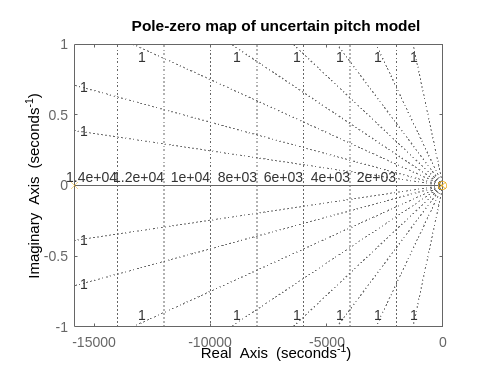

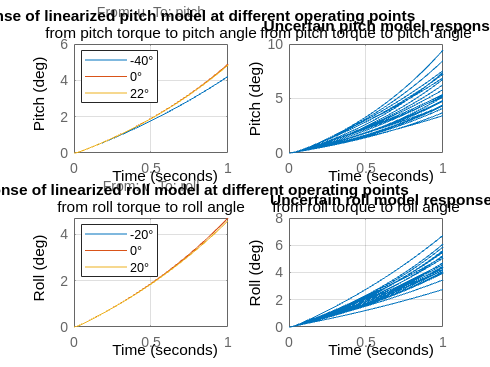

create_uncertain_models;

tf(tfu_pitch.NominalValue)

Incorrect number or types of inputs or outputs for function 'disp'.




launch_autotune;